clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

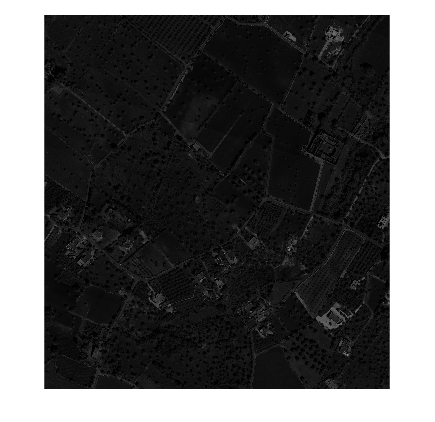

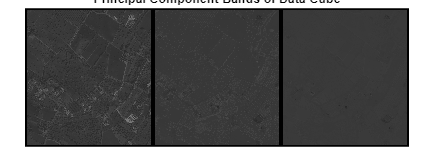

% Calculating PCA
[image,components] = PCA(hcube,3);

% k-means++ clustering
num_clusters = 4;

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% Set options
opts = statset('Display','final','MaxIter',10000);

% Run k-means++ with 'plus' option
[idx, centers] = kmeans(pixels, num_clusters, 'Start', 'plus', 'Options', opts);

Replicate 1, 48 iterations, total sum of distances = 90243.2.


Best total sum of distances = 90228.5


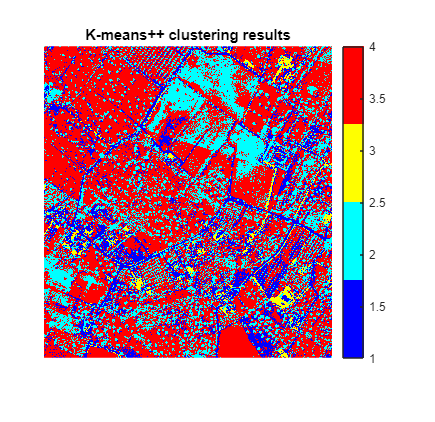


% Obtaining image's sizes
[rows, cols, ~] = size(image);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(num_clusters));
colorbar;
title('K-means++ clustering results');